clc
clear

dataset_folder = "/home/siyuchen/Documents/20231116/20231116_111833";
left_valid_id = load(fullfile(dataset_folder, "valid_apriltag_id_l.mat")).imagesUsed;
right_valid_id = load(fullfile(dataset_folder, "valid_apriltag_id_r.mat")).imagesUsed;

% For the specified image ID within the sequence, visual markers are detectable in both 
% the left and right images.
fprintf('This pattern occurs across a total of %d images within the sequence for both cameras.\n', ...
    sum(left_valid_id & right_valid_id));

This pattern occurs across a total of 0 images within the sequence for both cameras.


fprintf('This pattern occurs across a total of %d images within the sequence for left camera.\n', ...
    sum(left_valid_id));

This pattern occurs across a total of 633 images within the sequence for left camera.


fprintf('This pattern occurs across a total of %d images within the sequence. for right camera.\n', ...
    sum(right_valid_id));

This pattern occurs across a total of 952 images within the sequence. for right camera.


% Set the properties of the calibration pattern.
tagArrangement = [5,8];
tagFamily = "tag36h11";

is_left = false;

valid_id = left_valid_id;
if ~is_left
    valid_id = right_valid_id;
end


image_to_select = 48;

% Detect the calibration pattern from the images.
[imagePoints,boardSize, imagesUsed, selectedIndices] = helperDetectAprilTagCorners(dataset_folder, valid_id , image_to_select , is_left, tagArrangement,tagFamily);

        1752        1926        2162        1477        1664        2283        1670        1941        2169        2282        1934        1359        1288        1899        1849        2245        2017        1938        1791        1531        2240        1805        1283        1965        1785        1309        2143        1595        1501        1362        1575        1499        1918        1315        1541        1547        2125        1696        2009        1868        2033        1360        2234        2090        1300        1712        1584        1889



% Generate world point coordinates for the pattern.
tagSize = 15.5; % in millimeters

worldPoints = generateCheckerboardPoints(boardSize, tagSize);

% Determine the size of the images.
if is_left
    I = imread(fullfile(dataset_folder, sprintf('%06dL.jpg', selectedIndices(1))));
else
    I = imread(fullfile(dataset_folder, sprintf('%06dR.jpg', selectedIndices(1))));
end
imageSize = size(I,1:2);

% Estimate the camera parameters.
% can also be used for stereo camera calibration
params = estimateCameraParameters(imagePoints,worldPoints,ImageSize=imageSize);

Visualize the accuracy of the calibration and the extrinsic camera parameters. Show the planes of the calibration pattern in the captured images.

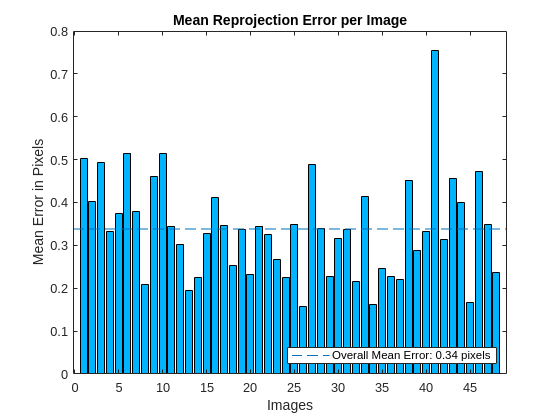

% Display the reprojection errors.
figure
showReprojectionErrors(params)

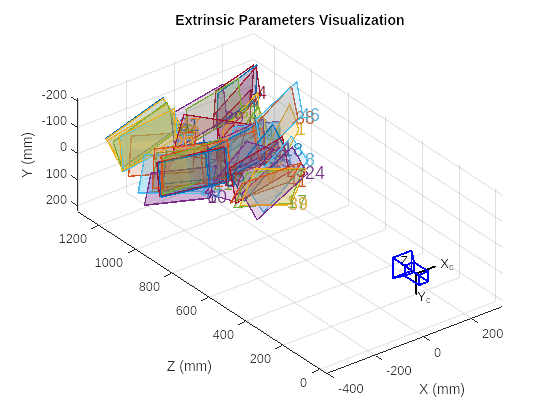

% Display the extrinsics.
figure
showExtrinsics(params)

Inspect the locations of the detected image points and the reprojected points, which were obtained using the estimated camera parameters.

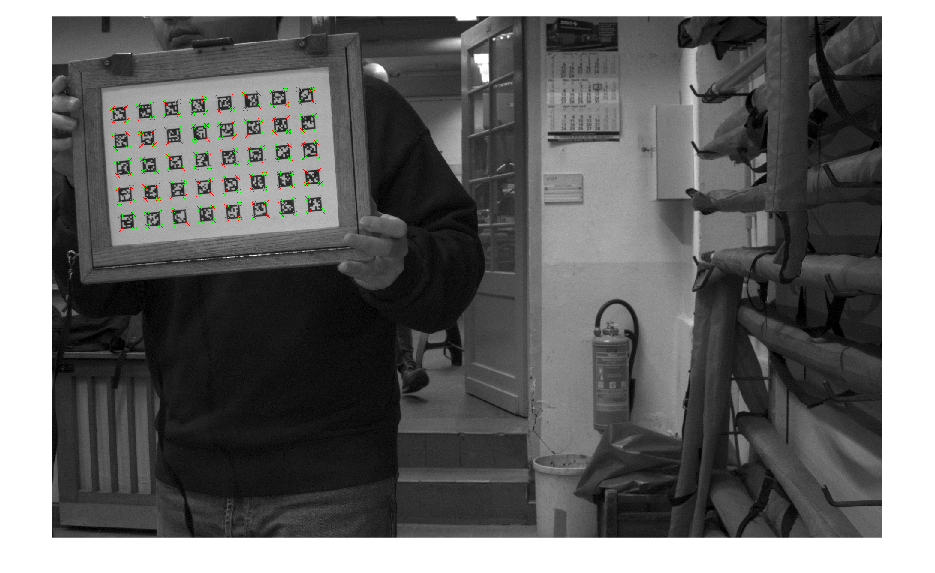

r_id = 20;
% Read a calibration image.
if is_left
    I = imread(fullfile(dataset_folder, sprintf('%06dL.jpg', selectedIndices(r_id))));
else
    I = imread(fullfile(dataset_folder, sprintf('%06dR.jpg', selectedIndices(r_id))));
end

% Insert markers for the detected and reprojected points.
I = insertMarker(I,imagePoints(:,:,r_id),"o",Color="g",Size=5);
I = insertMarker(I,params.ReprojectedPoints(:,:,r_id),"x",Color="r",Size=5);

% Display the image.
figure
imshow(I)

% Assume cameraParams is your cameraParameters object
intrinsicMatrix = params.K;
radialCoeff = params.RadialDistortion;
tangentialCoeff = params.TangentialDistortion;
imageSize = params.ImageSize;

% Now format these into a string in YAML format
yamlStr = sprintf('[fx, fy]: [%f, %f]\n', intrinsicMatrix(1, 1), intrinsicMatrix(2, 2));
yamlStr = [yamlStr, sprintf('[cx, cy]: [%f, %f]\n', intrinsicMatrix(1, 3), intrinsicMatrix(2, 3))];
yamlStr = [yamlStr, sprintf('[k1, k2]: [%f, %f]\n', radialCoeff)];
yamlStr = [yamlStr, sprintf('[p1, p2]: [%f, %f]\n', tangentialCoeff)];
yamlStr = [yamlStr, sprintf('imageSize: [%d, %d]\n', imageSize)];

% Write the string to a file
if is_left
    para_name = "left_cameraParams.yaml"
else
    para_name = "right_cameraParams.yaml"
end

para_name = "right_cameraParams.yaml"

fid = fopen(para_name, 'w');
fprintf(fid, yamlStr);
fclose(fid);

function [imagePoints, boardSize, imagesUsed, selectedIndices] = helperDetectAprilTagCorners(dataset_dir, valid_ids, num_to_select, is_left, tagArrangement,tagFamily)

% Find indices of 'true' elements
trueIndices = find(valid_ids);

% Check if there are at least 10 'true' elements
if length(trueIndices) >= num_to_select
    % Randomly shuffle the indices and pick the first 10
    selectedIndices = trueIndices(randperm(length(trueIndices), num_to_select));
else
    error('Not enough true elements in the vector.');
end

% Display the selected indices
disp(selectedIndices);

% Get the pattern size from tagArrangement.
boardSize = tagArrangement*2 + 1;

% Initialize number of images and tags.
numImages = num_to_select;
numTags = tagArrangement(1)*tagArrangement(2);

% Initialize number of corners in AprilTag pattern.
imagePoints = zeros(numTags*4, 2, numImages);
imagesUsed = zeros(1,numImages, "logical");

% Get checkerboard corner indices from AprilTag corners.
checkerIdx = helperAprilTagToCheckerLocations(tagArrangement);

for idx = 1:numImages
    % Read and detect AprilTags in image.
    if is_left
        I = imread(fullfile(dataset_dir, sprintf('%06dL.jpg', selectedIndices(idx))));
    else
        I = imread(fullfile(dataset_dir, sprintf('%06dR.jpg', selectedIndices(idx))));
    end
    [tagIds,tagLocs] = readAprilTag(I,tagFamily);

    % Accept images if all tags are detected.
    if numel(tagIds) == numTags
        % Sort detected tags using ID values.
        [~,sortIdx] = sort(tagIds);
        tagLocs = tagLocs(:,:,sortIdx);
        
        % Reshape tag corner locations into a M-by-2 array.
        tagLocs = reshape(permute(tagLocs,[1,3,2]),[],2);
        
        % Populate imagePoints using checkerboard corner indices.
        imagePoints(:,:,idx) = tagLocs(checkerIdx(:),:);
        imagesUsed(idx) = true; 
    else
        imagePoints(:,:,idx) = [];
    end
    
end

end

function checkerIdx = helperAprilTagToCheckerLocations(tagArrangement)

numTagRows = tagArrangement(1);
numTagCols = tagArrangement(2);
numTags = numTagRows * numTagCols;

% Row index offsets.
rowIdxOffset = [0:numTagRows - 1; 0:numTagRows - 1];

% Row indices for first and second columns in board.
col1Idx = repmat([4 1]',numTagRows,1);
col2Idx = repmat([3 2]',numTagRows,1);
col1Idx = col1Idx + rowIdxOffset(:)*4;
col2Idx = col2Idx + rowIdxOffset(:)*4;

% Column index offsets
colIdxOffset = 0:4*numTagRows:numTags*4 - 1;

% Implicit expansion to get all indices in order.
checkerIdx = [col1Idx;col2Idx] + colIdxOffset;

end